# `Progetto gruppo Delta`

clear;
close all;
clc;

addpath(['..',filesep,'modelli']) % Aggiungo la cartella dei modelli al path

[system,rigid_robot]=getRoboticSystem('Delta');

MacOS = false; 
    if MacOS
        fprintf("OS: MacOS");
        system.setForwardDynamics(@fdCodegen_mac);
    else
        fprintf("OS: Windows");
        system.setForwardDynamics(@fdCodegen_win);
    end

OS: Windows

Voglio vedere quali sono gli input e gli output, li stampo quindi a video.

fprintf('--- Nome input e output ---\n')

--- Nome input e output ---


u_max=system.getUMax;
for i_input=1:system.getInputNumber
    fprintf('Input %d: %s \t Valore massimo coppia in ingresso %.3f\n',i_input,system.getInputName{i_input},u_max(i_input));
end

Input 1: torque_1 	 Valore massimo coppia in ingresso 150.000
Input 2: torque_2 	 Valore massimo coppia in ingresso 150.000


for i_output=1:length(system.getOutputName)
    fprintf('Output %d: %s\n',i_output,system.getOutputName{i_output});
end

Output 1: position_1
Output 2: position_2
Output 3: velocity_1
Output 4: velocity_2


Tc = system.getSamplingPeriod; % Tempo di campionamento.
Fc = 2*pi/Tc; % Frequenza di campionamento.
fprintf(['Tempo di campionamento: %.3fs\n' ...
         'Frequenza di campionamento: %.3frad/s'],Tc,Fc);

Tempo di campionamento: 0.001s
Frequenza di campionamento: 6283.185rad/s

Definisco il sistema di controllo.

cs=ControlledSystemScara(system,'Delta');       

w_portante = 0.5;
a_portante = 75;  % Ampiezza -> circa il 70% dei limiti di coppia
w_min      = 10;
w_max      = 600;
n_sin_tot  = 60;
a_sin_max  = 35;
w_0_fitto  = 40;
w_1_fitto  = 300;
n_sin_fitto= 0;

n_wide_range = n_sin_tot-n_sin_fitto;

fprintf('Sinusoidi totali:\t%d\nSinusoidi range fitto:\t%d\nSinusoidi range ampio:\t%d',n_sin_tot,n_sin_fitto,n_wide_range)

Sinusoidi totali:	60
Sinusoidi range fitto:	0
Sinusoidi range ampio:	60

T_portante = 2*pi/w_portante

T_portante = 12.5664

t_sim=(0:Tc:(1.1*T_portante))';
portante=a_portante*sin(w_portante*t_sim);

%w_multisin=logspace(log10(w_min),log10(w_max),n_sin_tot)';
w_multisin=sort([logspace(log10(w_min),log10(w_max),n_wide_range)' ; ...
                 logspace(log10(w_0_fitto),log10(w_1_fitto),n_sin_fitto)']);
w_multisin=round(w_multisin/w_portante)*w_portante; % arrotondo per avere le omega multiple della portante
w_multisin=unique(w_multisin);
fprintf('Numero sinusoidi effettivamente usate:\t%d',length(w_multisin))

Numero sinusoidi effettivamente usate:	60

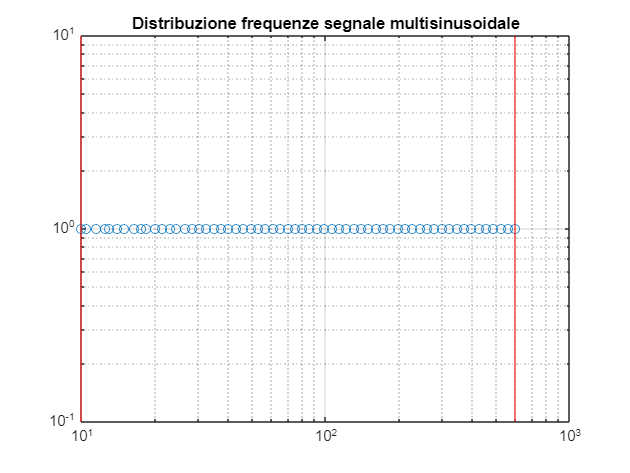

figure()
loglog(w_multisin,ones(1,length(w_multisin)),'o')
hold on
xline(w_min,'r')
xline(w_max,'r')
if n_sin_fitto > 0
    xline(w_0_fitto,'-.r')
    xline(w_1_fitto,'-.r')
end
title('Distribuzione frequenze segnale multisinusoidale')
grid on

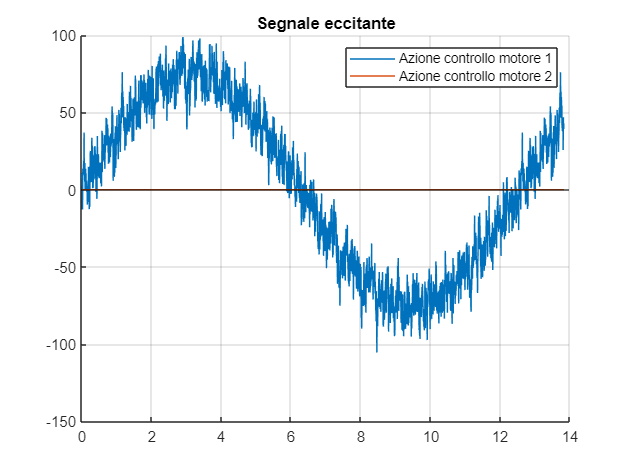

multisin=zeros(length(t_sim),1); % Inizializzo un segnale come vettore di tutti 0 di lunghezza t_sim.

for idx=1:length(w_multisin)
    fase=rand*2*pi;
    coeff_sin=sin(fase);
    coeff_cos=cos(fase);
    multisin=multisin+coeff_sin*sin(w_multisin(idx)*t_sim)+coeff_cos*cos(w_multisin(idx)*t_sim);
end

multisin=multisin/max(multisin)*a_sin_max;
exciting_signal = portante + multisin;

control_action=zeros(length(t_sim),system.getInputNumber); % Inizializzo vettore azione di controllo

control_action(:,1) = exciting_signal;

figure()
hold on
grid on
yline(0,'black')
plot(t_sim,control_action(:,1),t_sim,control_action(:,2))
legend('','Azione controllo motore 1','Azione controllo motore 2')
title("Segnale eccitante")

cs.initialize
y=zeros(4,1);
for idx=1:length(t_sim)
    control_action(idx,2)=-y(2)*0.1-y(4)*5;
    [process_output(idx,:),t(idx,1)]=cs.openloop(control_action(idx,:));
end

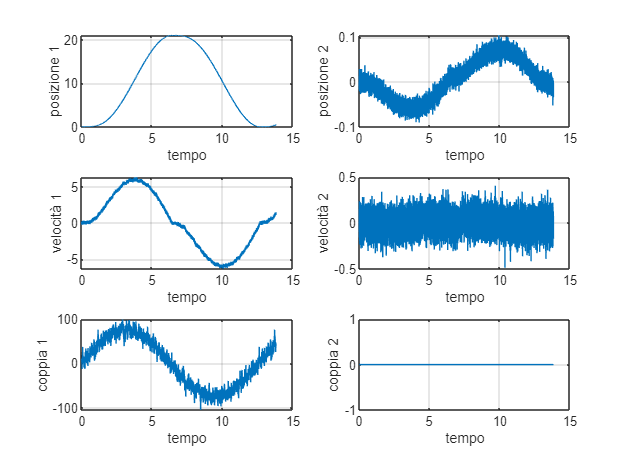

pos1=process_output(:,1);   vel1=process_output(:,3);   tau1=control_action(:,1);
pos2=process_output(:,2);   vel2=process_output(:,4);   tau2=control_action(:,2);

figure()
subplot(3,2,1), plot(t,pos1), grid on, xlabel('tempo'), ylabel('posizione 1')
subplot(3,2,2), plot(t,pos2), grid on, xlabel('tempo'), ylabel('posizione 2')
subplot(3,2,3), plot(t,vel1), grid on, xlabel('tempo'), ylabel('velocità 1' )
subplot(3,2,4), plot(t,vel2), grid on, xlabel('tempo'), ylabel('velocità 2' )
subplot(3,2,5), plot(t,tau1), grid on, xlabel('tempo'), ylabel('coppia 1'   )
subplot(3,2,6), plot(t,tau2), grid on, xlabel('tempo'), ylabel('coppia 2'   )               

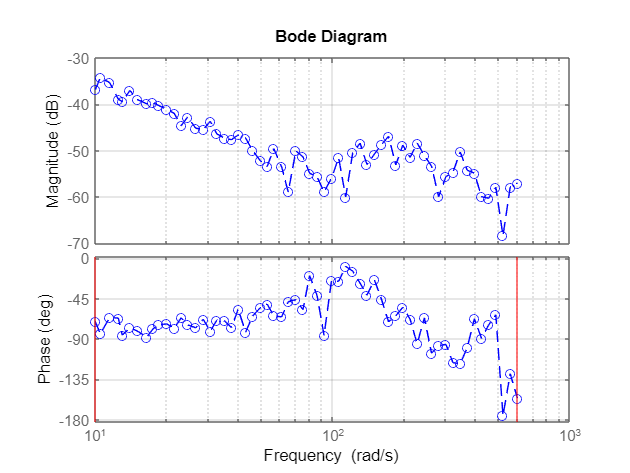

control_action_coef=fourierCoefficients(t, exciting_signal    , w_portante, w_multisin);
process_output_coef=fourierCoefficients(t, process_output(:,3), w_portante, w_multisin);

freq_resp=idfrd(process_output_coef./control_action_coef,w_multisin,Tc); % Y(i*omega)/U(i*omega)

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

figure
bodeplot(freq_resp,'--o', bode_opts);
grid on
hold on
xline(w_min,'r')
xline(w_max,'r')

if n_sin_fitto > 0
    xline(w_0_fitto,'-.r')
    xline(w_1_fitto,'-.r')
end

## Stima del modello

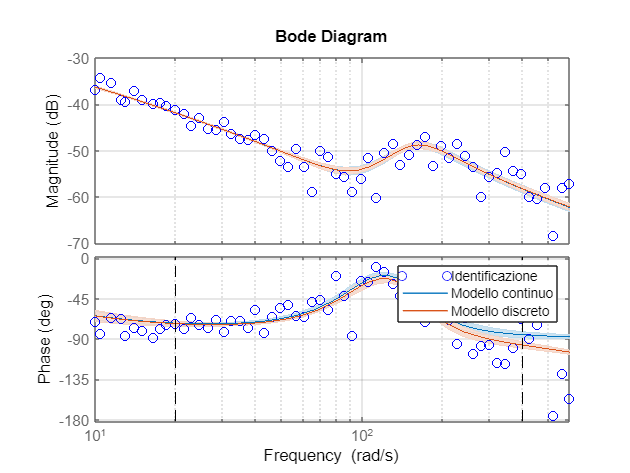

peso=ones(length(freq_resp.Frequency),1);
wpeso0=20;
wpeso1=400;
peso(freq_resp.Frequency<wpeso0)=1e-5;
peso(freq_resp.Frequency>wpeso1)=1e-5;
 
opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
mc = ssest(freq_resp,3,opts);
md = ssest(freq_resp,3,'Ts',Tc,opts);

figure
h=bodeplot(freq_resp,'o', bode_opts);
showConfidence(h,3)
hold on
bode(mc,md, bode_opts)
xlim([w_multisin(1) w_multisin(end)])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')
grid on
legend('Identificazione','Modello continuo','Modello discreto')
grid on

## Validazione - ancora da sistemare

Ottenuto il diagramma di Bode per il segnale eccitante precedente, vado ora ad effettuare la prova di validazione. Per fare questa prova costruisco un segnale eccitante differente da quello di partenza; in precedenza ho preso un segnale multisinusoidale, in questo caso andrò a prendere un segnale chirp. È consigliato cambiare i valori relativi alla portante.

In questo caso si costruisce quindi un segnale chirp con una portante. 

ProvaValidazione = false; 
if ProvaValidazione
omega_portante_val = 0.5;
a_portante_val = 90;
T_portante_val = 2*pi/omega_portante_val;
t_val = (0:Tc:(1.1*T_portante_val))';
portante_val = a_portante_val*sin(omega_portante_val*t_val);
w0_chirp = omega_portante_val*20;
w1_chirp=pi/Tc;
chirp_val = chirp(t_val,w0_chirp/2/pi,t_val(end),w1_chirp/2/pi,'logarithmic');
a_val = 150-a_portante_val;
exciting_signal_val = portante_val+chirp_val*a_val;
figure
plot(t_val,exciting_signal_val)
xlabel('time')
ylabel('input')
grid on
control_action_val=zeros(length(t_val),system.getInputNumber); % Inizializzo vettore azione di controllo

control_action_val(:,1) = exciting_signal_val;
cs.initialize
for idx=1:length(t_val)
    [process_output_val(idx,:),t2(idx,1)]=cs.openloop(control_action_val(idx,:));
end

validation=iddata(process_output_val(:,3),exciting_signal_val,Tc);
freq_resp_val = spafdr(validation);
figure
bode(freq_resp_val,'or',freq_resp,bode_opts)
hold on
plot(w0_chirp*[1 1],ylim,'--r')
hold off
grid on
legend('Validazione','Identificazione')
end